## *A. *Acquisition of the EMG signal

An EMG signal is loaded in ***.wav*** format with the ***audioread*** function, which extracts the information from the file and saves it in an matrix called ***EMG***, and the value of the sampling frequency of the loaded signal is stored in a variable called ***fm***.

[EMG,fm]=audioread('EMG0.wav')

EMG =     0.0889    0.4159
    0.0886    0.4245
    0.0883    0.4271
    0.0879    0.4267
    0.0876    0.4100
    0.0872    0.3956
    0.0869    0.3948
    0.0865    0.3866
    0.0862    0.3814
    0.0859    0.3843


fm = 11025

As can be seen, the ***EMG*** variable has two column vectors stored, each corresponding to a different EMG signal. On the other hand, if desired, you can hear both signals with the function ***soundsc***, this works to give an audible indication on the quality of the signal and thus have an approximation on which signal is noisier, as you hear next, as can show it sonorously, signal 2 is noisier.

First column of the matrix ***EMG***.

soundsc(EMG(:,1),fm)

Second column of the matrix ***EMG***.

soundsc(EMG(:,2),fm)

Both signals are plotted, so that it is verified that the EMG signal of the second column, unlike the EMG signal of the first, has so much noise that it is not possible to identify the behavior of the biosignal. Hence, it is chosen to process it and demonstrate the importance of digital processing in these biosignals.

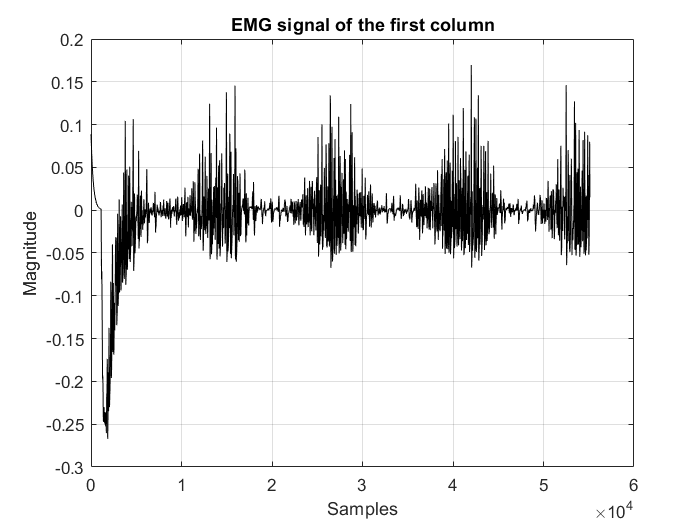

figure
plot(EMG(:,1),'k')
title('EMG signal of the first column')
xlabel('Samples'),ylabel('Magnitude'),grid on

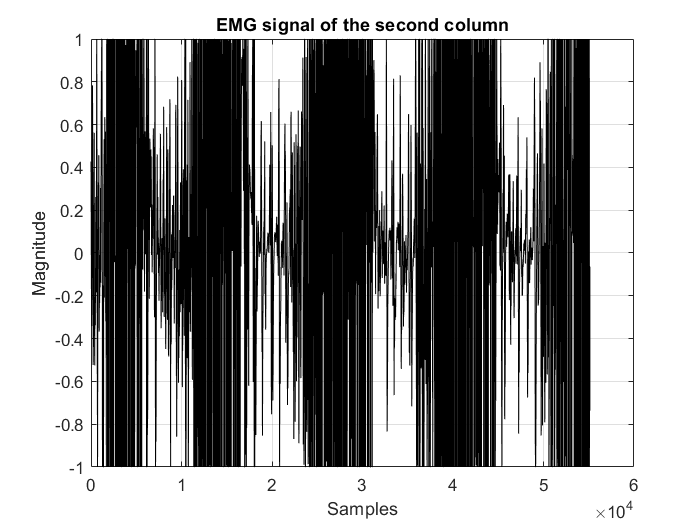

figure
plot(EMG(:,2),'k')
title('EMG signal of the second column')
xlabel('Samples'),ylabel('Magnitude'),grid on

## *  B. Digital Processing of EMG Signals*

Now, the digital processing of the EMG signal of the second column will be performed, which will be understood as the Raw EMG signal contained in the variable ***EMGR***.

## *    1) Load and characterization of variables*

After loading the signal into MATLAB, the discrimination of its intrinsic characteristics is performed, such as time, magnitude and sampling frequency, which is a fundamental value for subsequent processing.

The sampling period ***tm*** in seconds (s) is calculated from the sampling frequency ***fm*** in Hertz (Hz), following the equation of the period:


$$\mathrm{tm}=\frac{1}{\mathrm{fm}}$$


fm

fm = 11025

tm=1/fm

tm = 9.0703e-05

The EMG signal of interest is divided into a separate row vector called ***EMGR*** for subsequent processing, using the matrices processing syntax of MATLAB.

EMG

EMG =     0.0889    0.4159
    0.0886    0.4245
    0.0883    0.4271
    0.0879    0.4267
    0.0876    0.4100
    0.0872    0.3956
    0.0869    0.3948
    0.0865    0.3866
    0.0862    0.3814
    0.0859    0.3843


EMGR=EMG(:,2)'

EMGR =     0.4159    0.4245    0.4271    0.4267    0.4100    0.3956    0.3948    0.3866    0.3814    0.3843    0.3810    0.3731    0.3694    0.3712    0.3607    0.3517    0.3410    0.3357    0.3312    0.3093    0.2846    0.2587    0.2440    0.2239    0.1823    0.1421    0.1098    0.0647    0.0358    0.0251    0.0082   -0.0033   -0.0150   -0.0277   -0.0355   -0.0267   -0.0182   -0.0051    0.0126    0.0167    0.0186    0.0170    0.0048   -0.0187   -0.0426   -0.0776   -0.1195   -0.1447   -0.1650   -0.1860


The number of samples or data of the EMG signal is obtained with the function ***length***, which calculates the length of a vector, and is stored in the vector ***N***.

N=length(EMGR)

N = 55125

A time vector ***t*** is created, corresponding to the real time duration of the study signal, which is calculated from the number of samples with the vector creation syntax, $\textrm{start}:\textrm{step}:\textrm{end}$, the start is $t=0$, the step is the sample time ***tm*** and the end is the equivalent to the total time (in seconds) of all samples ***time***, subtracting a sample ***tm*** because that time is taken by the start value, zero.

time=N*tm

time = 5

t=0:tm:time-tm

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0044


Finally, a value f0 is calculated which denotes the relation: frequency per sample.

f0=fm/N

f0 = 0.2000

Once with this data in the Workspace, graphs can be generated that show the behavior of the Raw EMG signal, both in time and in frequency.

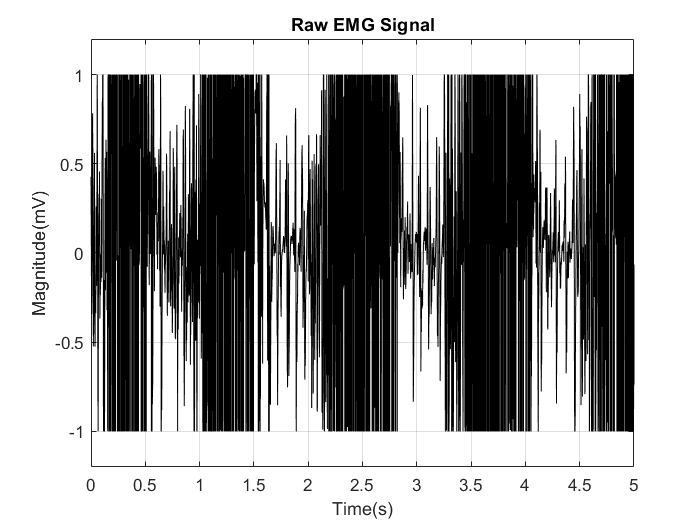

figure
plot(t,EMGR,'k')
title('Raw EMG Signal')
xlabel('Time(s)'),ylabel('Magnitude(mV)'),grid on
ylim([-1.2 1.2])
xlim([0 time])

On the other hand, the calculation of the frequency spectrum of the ***EMGR*** signal is performed by the function ***fft*** that develops the fast Fourier transform


$${\textrm{EMG}F}_k =\sum_{n=0}^{N-1} {\textrm{EMGR}}_n e^{-\frac{\textrm{i2}\pi \textrm{kn}}{N}} ,\;\;\;\;k=0,\ldotp \ldotp \ldotp ,N-1\ldotp$$
 

on the biosignal studied.

EMGF=fft(EMGR);

Following this, the absolute value of the transformed signal ***EMGF*** is obtained with the function ***abs*** and this frequency spectrum is plotted against the half of the sampling frequency.

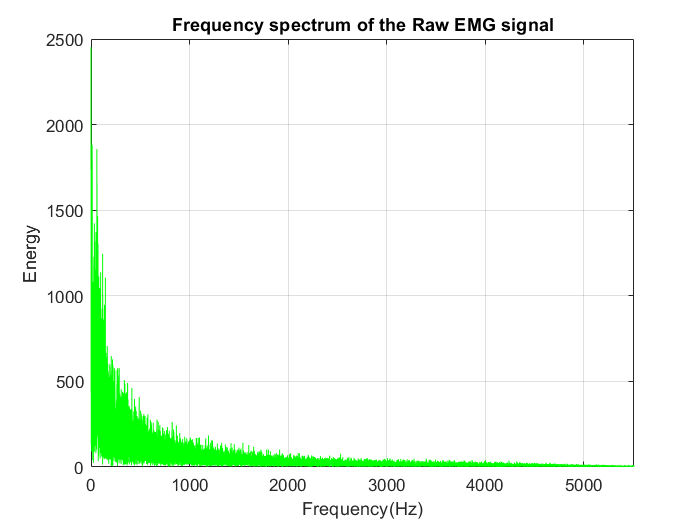

figure
plot(f0*(0:N-1),abs(EMGF),'g')
title('Frequency spectrum of the Raw EMG signal')
xlabel('Frequency(Hz)'),ylabel('Energy'),grid on
xlim([0 fm/2])

##     2) *Offset elimination *

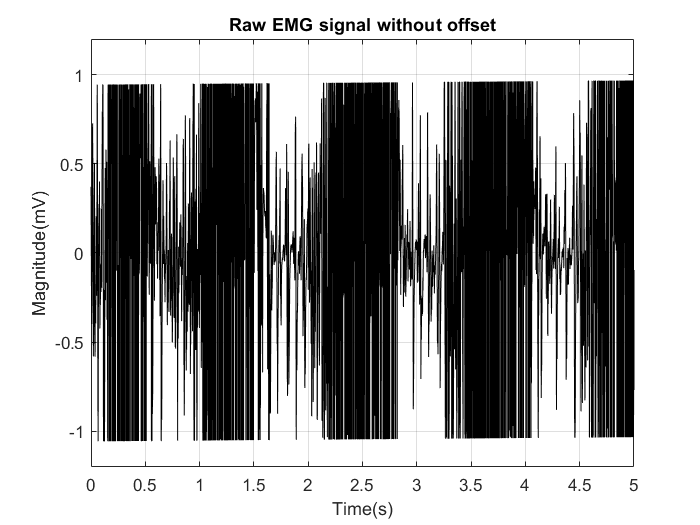

EMGR=detrend(EMGR);
figure
plot(t,EMGR,'k')
title('Raw EMG signal without offset')
xlabel('Time(s)'),ylabel('Magnitude(mV)'),grid on
ylim([-1.2 1.2])
xlim([0 time])

##     3) *Bandpass filter EMG: 4Hz to 500Hz*

EMG signals have their most relevant information in the frequency band between 4Hz and 500Hz, for that reason, this is taken as a criterion for the design of a band pass filter, which can to be understood as a filter passes high in series with a low pass filter, with cutoff frequencies of 4Hz to pass high frequencies ***cb*** and 500Hz for low frequencies ***ca***.

First, the specified cutting frequencies are loaded.

cb=4;
ca=500;

Then the coefficients ***a*** and ***b*** of the Butterworth filter are calculated, specifying order 4 and calculating the normalized cutoff frequency by means of the equation

 $\textrm{Fcn}=\textrm{Fc}*\frac{1}{\frac{\textrm{fm}}{2}}$.

where **Fcn** is the normalized cutoff frequency, **Fc** is the selected cutting frequency in Hertz and ***fm*** is the sampling frequency. 

[b,a]=butter(4,[cb*2/fm ca*2/fm])

b =     0.0003         0   -0.0011         0    0.0017         0   -0.0011         0    0.0003


a =     1.0000   -7.2601   23.0845  -41.9921   47.8024  -34.8741   15.9239   -4.1609    0.4764


After this, the bandpass filter designed on the Raw EMG signal is applied and stored in a variable called ***EMGf1***, corresponding to "EMG signal with filter 1".

EMGf1=filter(b,a,EMGR);

Finally, the signal is plotted to observe the changes, both in time, without limits in Y, and in the frequency, with a limit in X up to 1500Hz to make the effect of the filter more noticeable.

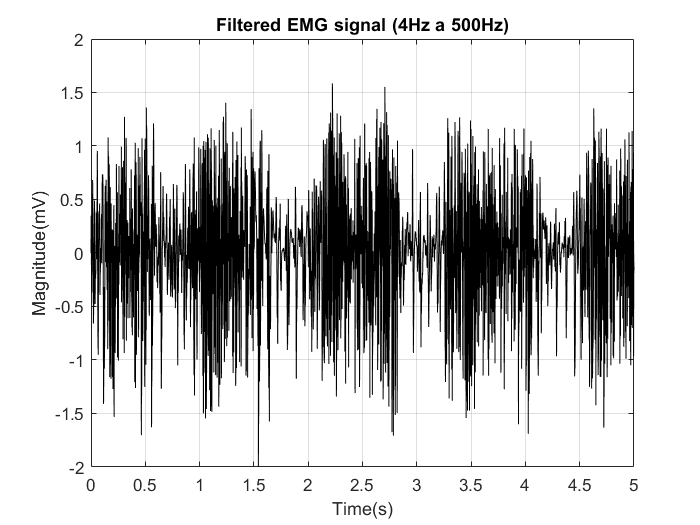

figure
plot(t,EMGf1,'k')
title('Filtered EMG signal (4Hz a 500Hz)')
xlabel('Time(s)'),ylabel('Magnitude(mV)'),grid on
xlim([0 time])

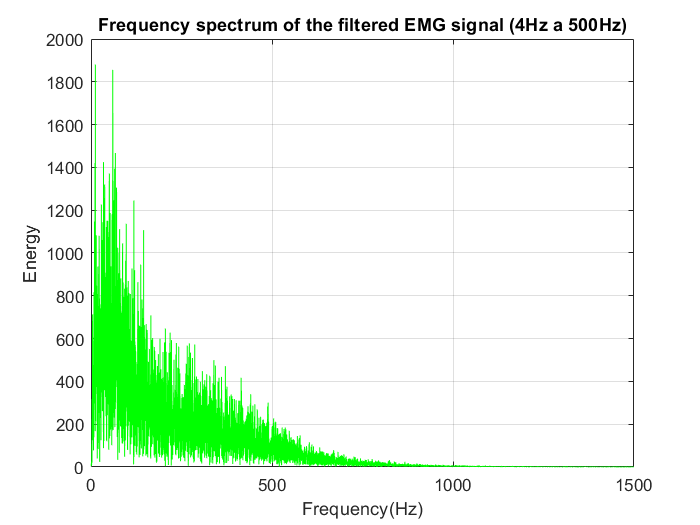

EMGF1=fft(EMGf1);
figure
plot(f0*(0:N-1),abs(EMGF1),'g')
title('Frequency spectrum of the filtered EMG signal (4Hz a 500Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy'),grid on
xlim([0 1500])

##     4) *Band-stop filter*: 60Hz

Now, the same procedure is carried out for the design of a 60Hz band-stop filter, since this EMG signal has been acquired the frequency of the electric line is 60Hz. Now a specification is added to the function ***butter***, called ***'stop'***, and that the cutting frequencies are $\textrm{cb}=57$ y $\textrm{ca}=63$, with order 3, to ensure the stability of the filter. This filter is applied to the ***EMGf1*** signal, this is called cascade filtering, one after another, and stored in ***EMGf2***.

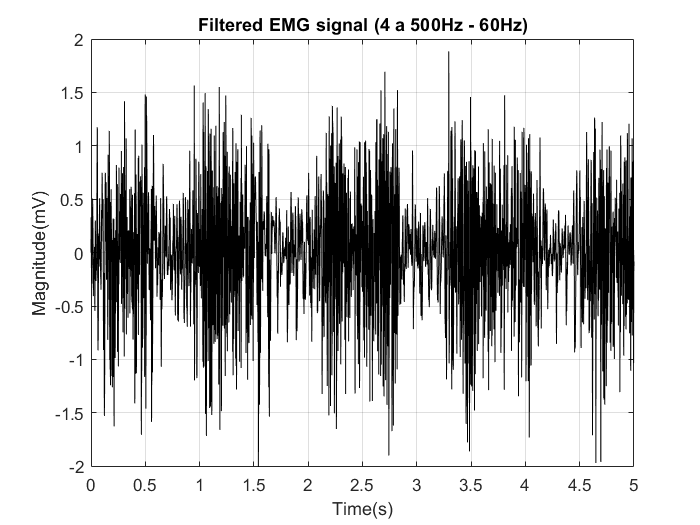

cb=57;
ca=63;
[b,a]=butter(3,[cb*2/fm ca*2/fm],'stop');
EMGf2=filter(b,a,EMGf1);
EMGF2=fft(EMGf2);

figure
plot(t,EMGf2,'k')
title('Filtered EMG signal (4 a 500Hz - 60Hz)')
xlabel('Time(s)'),ylabel('Magnitude(mV)'),grid on
xlim([0 time])

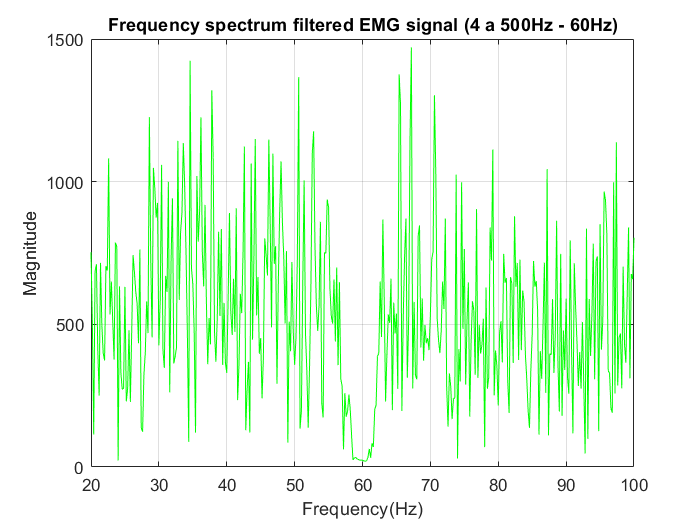

figure
plot(f0*(0:N-1),abs(EMGF2),'g')
title('Frequency spectrum filtered EMG signal (4 a 500Hz - 60Hz)')
xlabel('Frequency(Hz)'),ylabel('Magnitude'),grid on
xlim([20 100])

## 3. Filter result

Next, the results are presented, comparing the Raw EMG signal with the filtered EMG signal. First, the filtered EMG signal ***EMGf2*** is plotted in black and the Raw EMG signal ***EMGR*** in red. Then, their respective frequency spectrum are plotted in the same way and colors.

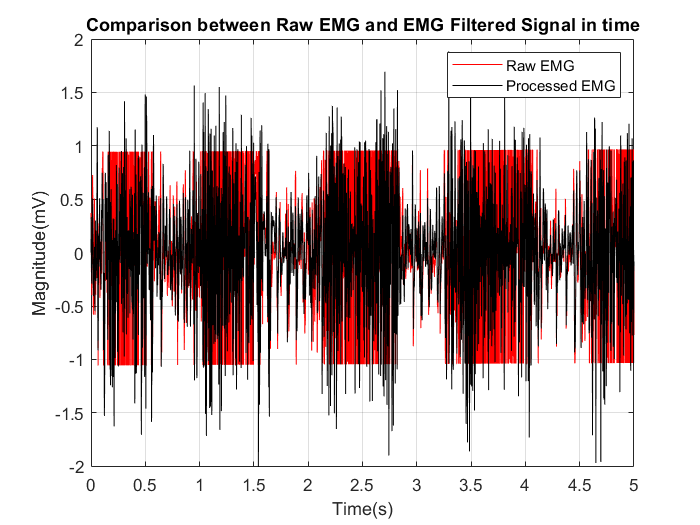

figure
plot(t,EMGR,'r')
hold on
plot(t,EMGf2,'k')
title('Comparison between Raw EMG and EMG Filtered Signal in time')
xlabel('Time(s)'),ylabel('Magnitude(mV)'),grid on
xlim([0 time])
legend('Raw EMG','Processed EMG')

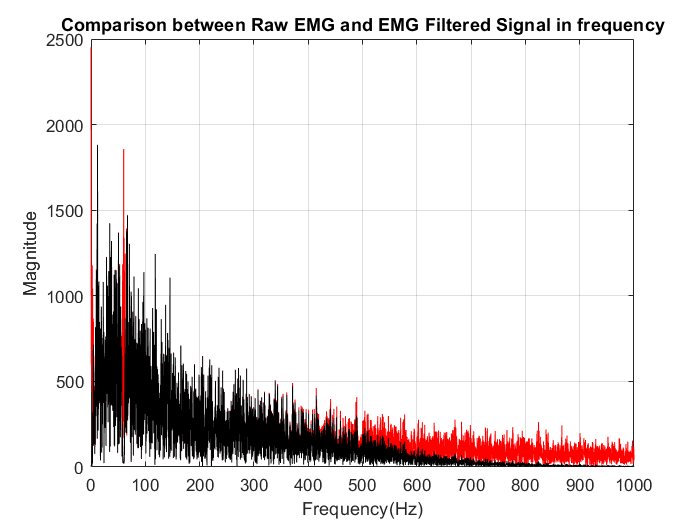


figure
plot(f0*(0:N-1),abs(EMGF),'r')
hold on
plot(f0*(0:N-1),abs(EMGF2),'k')
title('Comparison between Raw EMG and EMG Filtered Signal in frequency')
xlabel('Frequency(Hz)'),ylabel('Magnitude'),grid on
xlim([0 1000])

To end with this section, the comparison between the sounds of both signals is also allowed, where the radical change of sound in the EMG signal can be appreciated after processing it.

By executing the next section of code you can hear the Raw EMG signal.

soundsc(EMGR,fm)

By executing the next section of code you can hear the Processed EMG signal.

soundsc(EMGf2,fm)